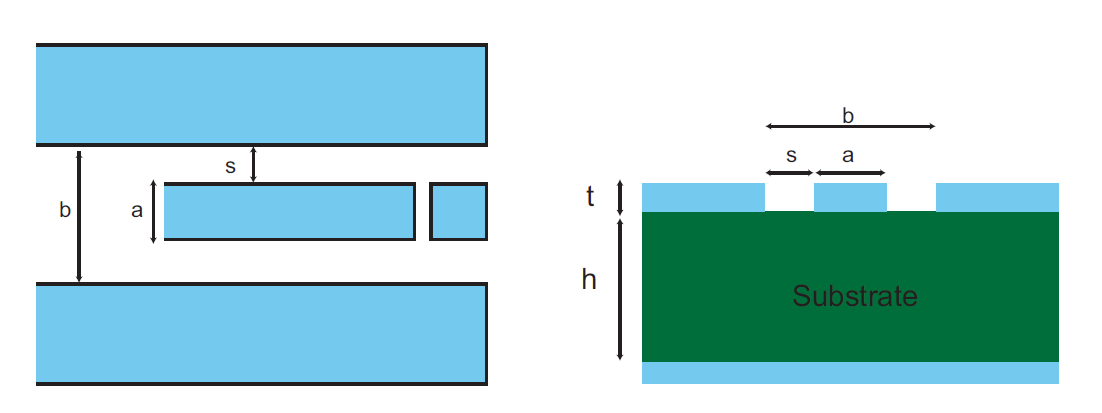

Fig 3.6 from Schuster's thesis

For CPT-NR PCB, a=1.15um, s=1.38um

Design in CAD: a=1.26um, s=0.75um

CPT PCB: a=

%%% define dimensions of CPW %%%%
s=.75;
a=1.26;
b=2*s+a;
h=300;   %300 um Si substrates
epsilon_r=11.9;  %%% for Si wafer

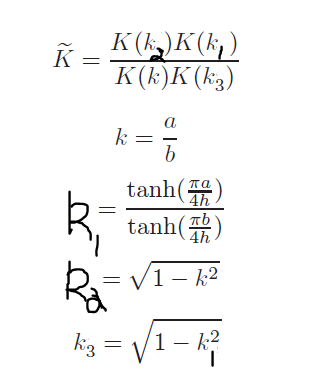

%%%% derived parameters  %%%%
k=a/b;
k1=tanh(pi*a/4/h)/tanh(pi*b/4/h);
k2=sqrt(1-k^2);
k3=sqrt(1-k1^2);
k_tilde=ellipke(k2)*ellipke(k1)/ellipke(k)/ellipke(k3);

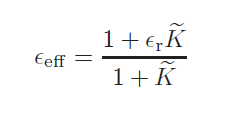

epsilon_eff=(1+epsilon_r*k_tilde)/(1+k_tilde);

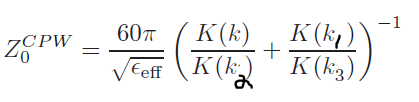

z0=60*pi/sqrt(epsilon_eff)/(ellipke(k)/ellipke(k2)+ellipke(k1)/ellipke(k3))

z0 = 51.6611